# Resizing an Image by Blocks

Instructions are in the task pane to the left. Complete and submit each task one at a time.

This code sets up the activity.

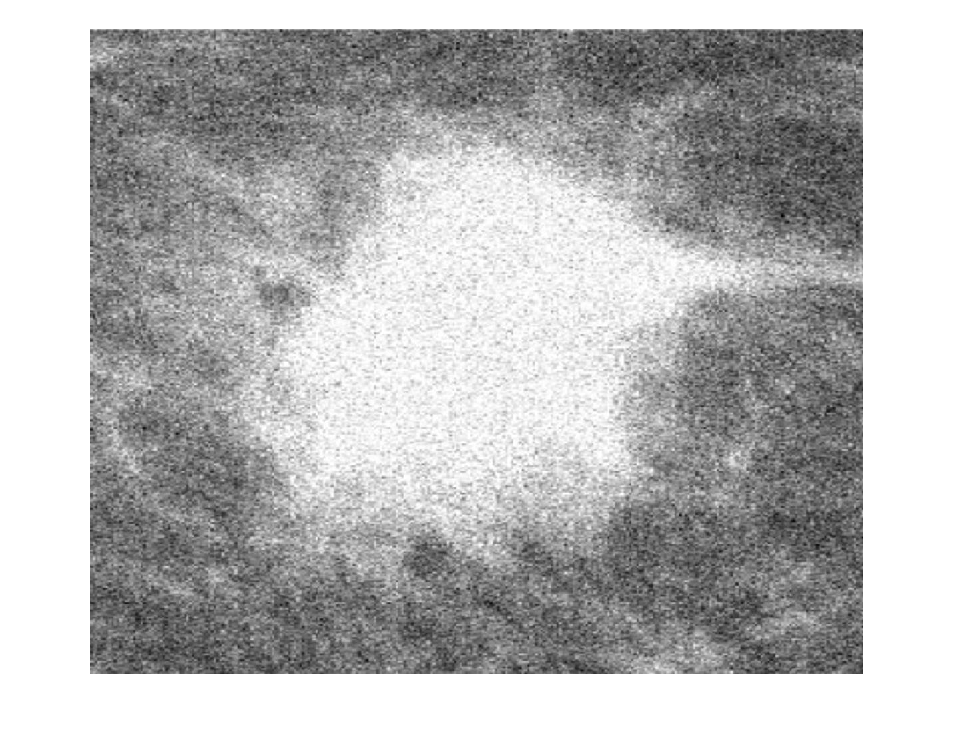

tumorOriginal = imread("./images/tumorLargeFile.jpg");
imshow(tumorOriginal)

## Task 2

To process an image by blocks, use `blockproc`.

`imBP` `=` `blockproc``(``im``,``blockSize``,@``functionName``)`

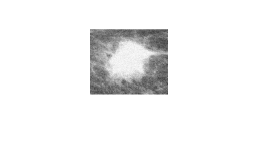

tumor = blockproc(tumorOriginal, [15 15], @shrinkImage);
imshow(tumor)

## Task 1

You will shrink the image of a tumor by replacing a block by its median value.

First, you will write a function that gets passed to `blockproc`. The function declaration for `shrinkImage` is at the bottom of the script, and you will fill in the body of this local function.

To access image data for a block within the block processing function, first extract the `data` field from the input structure, `blockStruct`.

`blockStruct.data`

You can calculate the median of *all* array elements with the `median` function.

`median``(``A``,``"all"``)`

function newBlock = shrinkImage(blockStruct)
    % shrinkImage extracts the block data from the input structure
    % and finds its median and returns that scalar as the output
    
    % extract the data field of the structure blockStruct
    block = blockStruct.data;
    
    % calculate the median of the data field and save to newBlock
    newBlock = median(block,"all");
end